# Lab 10 Report

LI Zhiying 12210309

## Problem1 -- Color wheels

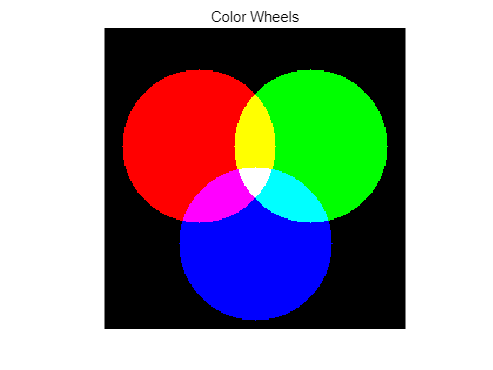

% i 
canva = 256;
Canva = zeros(canva, canva, 3);

distance = 55;
radius = 65;
center = (canva + 1) / 2;
Center = [center,center];
R_center = round([Center(1) - distance*cos(pi/3), Center(2) - distance*sin(pi/3)]);
G_center = round([Center(1) - distance*cos(pi/3), Center(2) + distance*sin(pi/3)]);
B_center = round([Center(1) + distance, Center(2)]);

for i = 1:canva
    for j = 1:canva
        if sqrt((i - R_center(1)).^2 + (j - R_center(2)).^2) <= radius
            Canva(i,j,1) = 1;
        end
        if sqrt((i - G_center(1)).^2 + (j - G_center(2)).^2) <= radius
            Canva(i,j,2) = 1;
        end
        if sqrt((i - B_center(1)).^2 + (j - B_center(2)).^2) <= radius
            Canva(i,j,3) = 1;
        end
    end
end                              
figure;
image(Canva); title('Color Wheels'); axis image; axis off

*Answer: *生成的图片与课堂中所讨论的Color Wheel 一致。

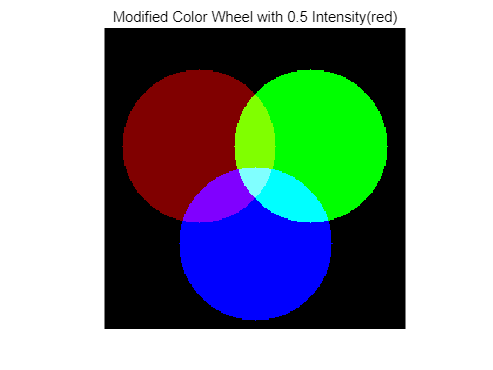

% ii
CanvaR = Canva;
CanvaG = Canva;
CanvaB = Canva;
CanvaR(:, :, 1) = CanvaR(:, :, 1).*0.5;
CanvaG(:, :, 2) = CanvaG(:, :, 2).*0.5;
CanvaB(:, :, 3) = CanvaB(:, :, 3).*0.5;

figure;
image(CanvaR); title('Modified Color Wheel with 0.5 Intensity(red)'); 
axis image; axis off

*Answer：* 当红色色轮强度改为0.5后，其与绿色、蓝色区域的重叠部分发生变化，绿色和蓝色逐渐占据主要成分。与绿色区域的重叠部分从黄色变为绿色，与蓝色区域的重叠部分变成紫色，三色区域重叠部分变蓝。

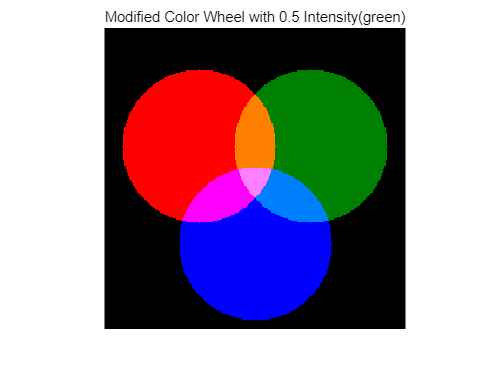

figure;
image(CanvaG); title('Modified Color Wheel with 0.5 Intensity(green)');
axis image; axis off

*Answer：* 当绿色色轮强度改为0.5后，其与红色、蓝色区域的重叠部分发生变化，红色和蓝色逐渐占据主要成分。与红色区域的重叠部分从黄色变为橙色，与蓝色区域的重叠部分从天蓝色变成更深的蓝色，三色区域重叠部分变粉。

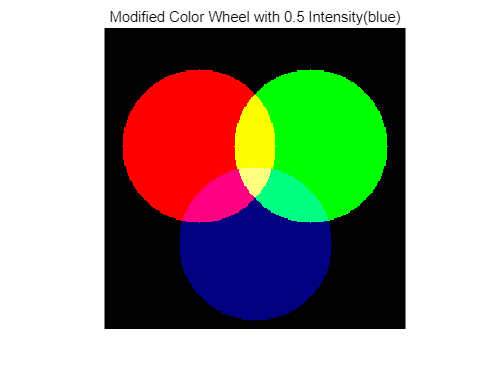

figure;
image(CanvaB); title('Modified Color Wheel with 0.5 Intensity(blue)');
axis image; axis off

*Answer：* 当蓝色色轮强度改为0.5后，其与红色、绿色区域的重叠部分发生变化，红色和绿色逐渐占据主要成分。与红色区域的重叠部分变得更红，与绿色区域的重叠部分从天蓝色变为偏绿的颜色，三色区域重叠部分变为淡黄色。

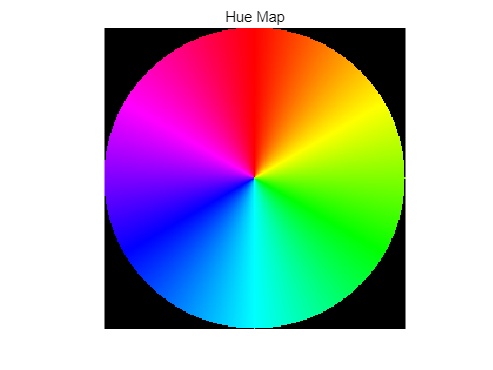

% iii
center_x = canva / 2;
center_y = canva / 2;
radius = canva / 2;

[delta_x,delta_y]  = meshgrid(1:canva,1:canva);

[delta,~] =  cart2pol(delta_x - center_x, delta_y - center_y);

hue = (mod(delta + pi/2 , 2*pi) / (2*pi));

S = sqrt((delta_x - center_x).^2 + (delta_y - center_y).^2) <= radius;

B = sqrt((delta_x - center_x).^2 + (delta_y - center_y).^2) <= radius;

hue_map = cat(3, hue, S, B);
rgb_hue_map = hsv2rgb(hue_map);

figure;
image(rgb_hue_map);
axis equal; axis image; axis off;
title('Hue Map');

## Problem2 -- RGB images

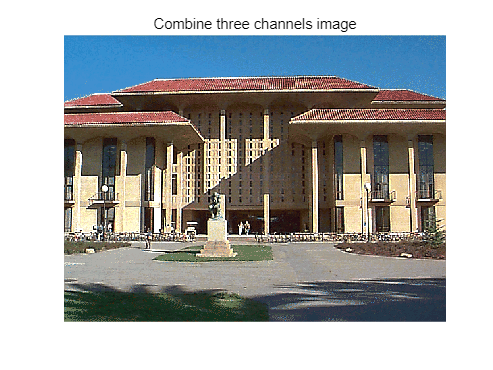

clear; clc;
fr = fopen('lab10prob2r');
fg = fopen('lab10prob2g');
fb = fopen('lab10prob2b');

imR = fread(fr,[580,435],'uint8');
imR = imR';
imG = fread(fg,[580,435],'uint8');
imG = imG';
imB = fread(fb,[580,435],'uint8');
imB = imB';

sum_im = cat(3,imR,imG,imB);
sum_im = sum_im / max(sum_im,[],'all');
figure;
image(sum_im);
axis equal; axis image; axis off;
title('Combine three channels image');

## Problem 3 False Color Image

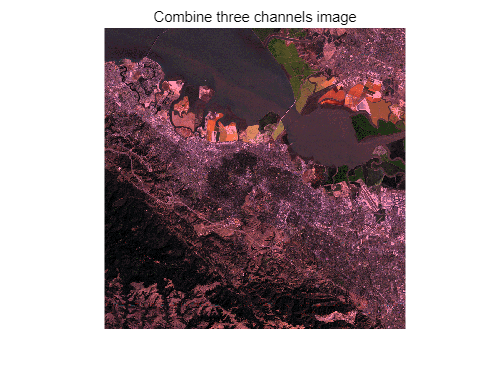

clear;clc;
fr = fopen('lab10prob3r');
fg = fopen('lab10prob3g');
fb = fopen('lab10prob3b');

imR = fread(fr,[1024, 1024], 'uint8');
imR = imR';
imG = fread(fg,[1024, 1024], 'uint8');
imG = imG';
imB = fread(fb,[1024, 1024], 'uint8');
imB = imB';

sum_im = cat(3,imR,imG,imB);
sum_im = sum_im / max(sum_im,[],'all');
figure;
image(sum_im);
axis equal; axis image; axis off;
title('Combine three channels image');

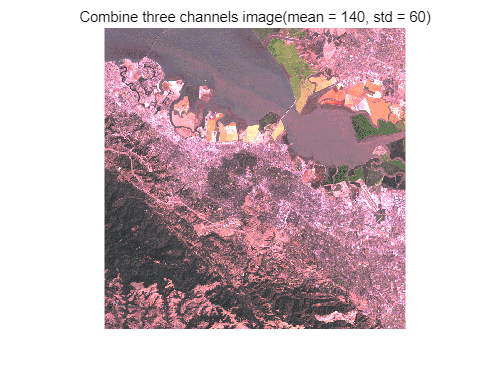

% i 
sum_im_double = im2double(sum_im);
mean_val = mean(sum_im_double(:));
std_val = std(sum_im_double(:));
sum_im_scale = 60 * ((sum_im_double - mean_val) / std_val) + 140;
sum_im_scale = uint8(sum_im_scale);
figure;
image(sum_im_scale);
axis equal; axis image; axis off;
title('Combine three channels image(mean = 140, std = 60)');

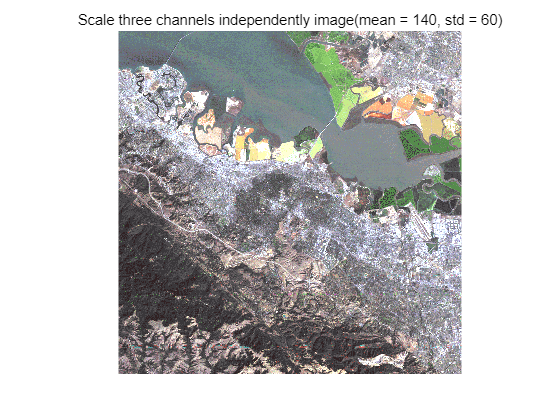

% ii
sum_img_scale_double = im2double(sum_im);
for i = 1:3
    chan = sum_im_double(:,:,i);
    mean_chan = mean(chan(:));
    std_chan = std(chan(:));
    sum_im_scale_channel = 60 * ((chan - mean_chan) / std_chan) + 140;
    sum_img_scale_double(:,:,i) = sum_im_scale_channel;
end
sum_img_scale_Channel = uint8(sum_img_scale_double);
figure;
image(sum_img_scale_Channel);
axis equal; axis image; axis off;
title('Scale three channels independently image(mean = 140, std = 60)');

Answer： 独立缩放对图像中特征区分能力的提高体现在以下几点：

- **突出各通道特征**: 每个通道的像素值都基于自身特性调整，而不是受其他通道的分布影响。这使得通道间特征对比更加清晰。

- **增强局部对比度**: 通道的独立调整可以增强局部特征的对比，使细节更加突出，尤其是在不同通道具有不同动态范围的情况下。

- **减小混淆**: 整体调整可能导致某些通道的特征被压缩或放大过度，降低对特定颜色或特征的分辨率。独立调整避免了这种混淆。

## Problem 3 -- Indexed color

clear; clc;
f = fopen('lab10prob4data');
img = fread(f, [580,435], 'uint8');
img = img';

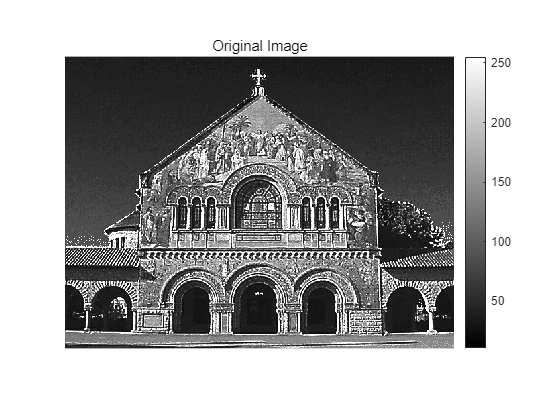

% i
figure;
imagesc(img);
axis image; axis off; colormap gray; colorbar;
title('Original Image');

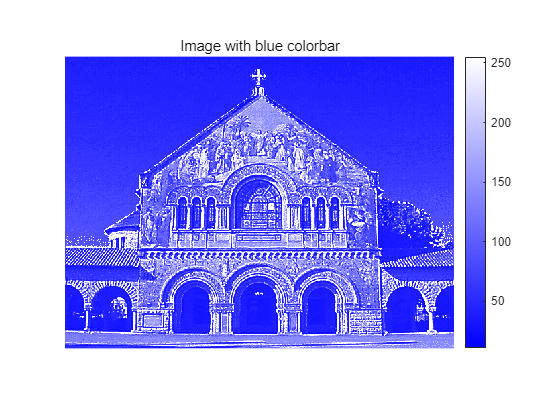

% ii
blue_map = [linspace(0,1,256)',linspace(0,1,256)',ones(256,1)];
figure;
imagesc(img);
axis image; axis off; colormap(blue_map); colorbar;
title('Image with blue colorbar');

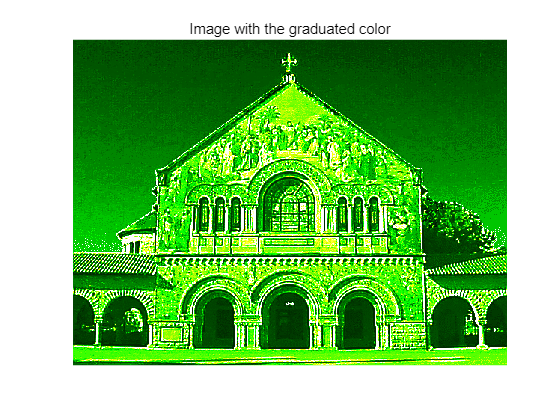

% iii
Colormap = zeros(256,3);

for i = 1:101
    Colormap(i,:) = [0 ,(i-1)/100, 0];
end
for i = 101:201
    Colormap(i,:) = [(i-101)/100, 1, 0];
end
for i = 201:256
    Colormap(i,:) = [1, 1, (i-201)/55];
end
figure;
imagesc(img);
axis image; axis off; colormap(Colormap); Colormap;
title('Image with the graduated color');

## Problem 5 – Saving our Eyes

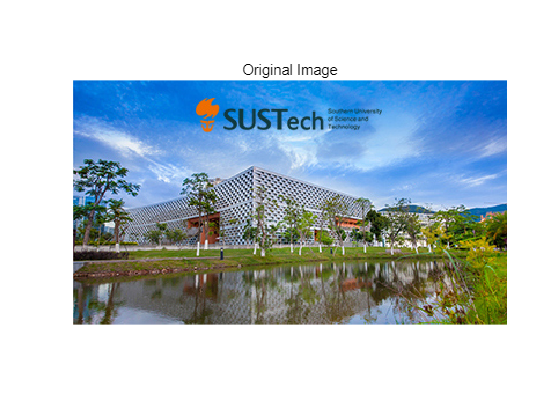

clear;clc;
% i
img = imread('testImage.jpg');
figure;
image(img);
axis image; axis off;
title('Original Image');

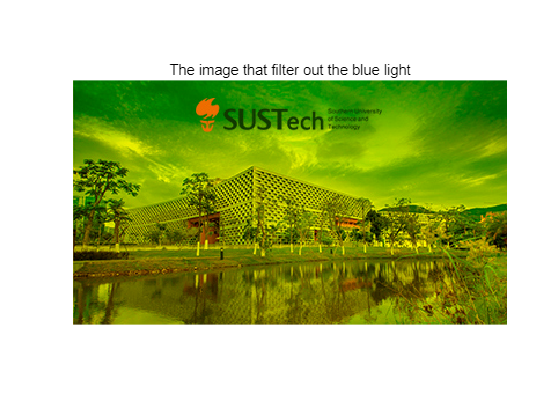

removeblue_img = img;
removeblue_img(:,:,3) = 0;
figure;
image(removeblue_img);
axis image; axis off;
title('The image that filter out the blue light');

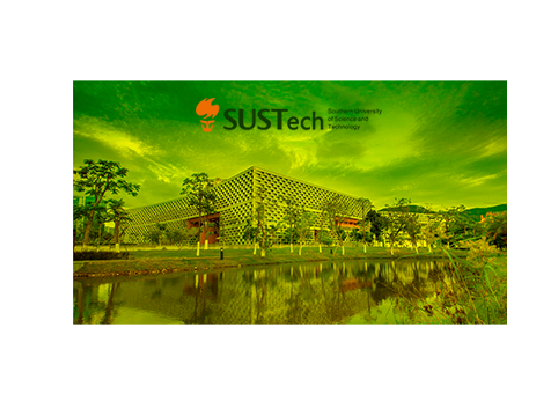

% ii
num_Frames = 100;
for w = 1:num_Frames
    blue_scale = (1 - (w - 1) / 99);
    currentFrame = img;
    currentFrame(:,:,3) = uint8(double(currentFrame(:,:,3)).*blue_scale);
    image(currentFrame);
    axis image; axis off;

    M(w) = getframe;
end

v = VideoWriter('FluxFade_12210309_Lzy','MPEG-4');
v.FrameRate = 25;
open(v);
writeVideo(v,M);
close(v);
warning('off')
clear;